% Definir la variable simbolica para la funcion de transferencia
s = tf('s');  

% Funciones de transferencia individuales
FdT_Planta = 1/(7.5*s^2 + 6.5*s + 1);         % Funcion de transferencia de la planta
FdT_Sensor = 0.01;                            % Funcion de transferencia del sensor
FdT_Ventilador = -0.0038/(s + 0.007);         % Funcion de transferencia del ventilador
FdT_Comparador = 16.67;                       % Funcion de transferencia del comparador
FdT_Inversor = -1;                            % Inversor 

% Definir la funcion de transferencia a lazo abierto (GH)
G=FdT_Planta*FdT_Ventilador*FdT_Comparador*FdT_Inversor;
H=FdT_Sensor;
disp('La función de transferencia a lazo abierto "GH"');

La función de transferencia a lazo abierto "GH"


GH=G*H

GH =
 
                0.0006335
  -------------------------------------
  7.5 s^3 + 6.553 s^2 + 1.046 s + 0.007
 
Continuous-time transfer function.




% Mostrar la funcion de transferencia a lazo abierto en forma de ceros y polos
disp('La función de transferencia a lazo abierto explicita');

La función de transferencia a lazo abierto explicita


GH=zpk(GH)  

GH =
 
           8.4461e-05
  ----------------------------
  (s+0.6667) (s+0.2) (s+0.007)
 
Continuous-time zero/pole/gain model.




% La ecuacion caracteristica de la funcion de transferencia a lazo abierto resulta ser:
% Ec(s) = (s+0.6667)(s^2 + 0.207s + 0.0014)

% Diseño del PID
% La forma del PID es: PID = kp * (Ti*Td*s^2 + Ti*s + 1) / (Ti*s)

% Vamos a igualar terminos con la ecuacion de segundo orden en el denominador

% Comparacion con la ecuacion de segundo orden:
% a^2 + b*s + c = s^2 + 0.207*s + 0.0014

c = 1;               % Valor de c (termino constante)
b = 0.207/0.0014;    % Calculamos b
a = 1/0.0014;        % Calculamos a

Ti = b              

Ti = 147.8571

Td = a/Ti        

Td = 4.8309


% Armamos el controlador PID utilizando los valores de Ti y Td
PID =(Ti*Td*s^2 +Ti*s+1)/(Ti*s) 

PID =
 
  714.3 s^2 + 147.9 s + 1
  -----------------------
          147.9 s
 
Continuous-time transfer function.




% Armamos la funcion de transferencia a lazo abierto compensado (con PID)
FdT_Global_PID = PID*GH

FdT_Global_PID =
 
   0.00040803 (s+0.2) (s+0.007)
  ------------------------------
  s (s+0.6667) (s+0.2) (s+0.007)
 
Continuous-time zero/pole/gain model.



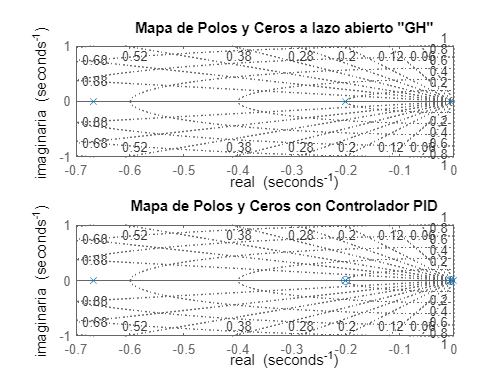


% Verificamos la cancelacion de polos
figure;
subplot(2,1,1);                  % Primer subplot para la funcion a lazo abierto
pzmap(GH);       % Muestra el mapa de polos y ceros de la funcion a lazo abierto
title('Mapa de Polos y Ceros a lazo abierto "GH"');
xlabel('real');
ylabel('imaginaria');
grid on;

subplot(2,1,2);          % Segundo subplot para la funcion con PID
pzmap(FdT_Global_PID);  % Muestra el mapa de polos y ceros de la funcion compensada
title('Mapa de Polos y Ceros con Controlador PID');
xlabel('real');
ylabel('imaginaria');
grid on;      


% Simplificamos la expresion para obtener una forma mas compacta
FdT_Global_PID = minreal(FdT_Global_PID)  % Simplificacion de la fdt

FdT_Global_PID =
 
   0.00040803
  ------------
  s (s+0.6667)
 
Continuous-time zero/pole/gain model.




% Usamos el lugar de las raices para encontrar el valor de kp
% El lugar de las raices nos permite obtener el valor de kp que
% satisface las especificaciones

figure;
rlocus(FdT_Global_PID);         
grid on;                          
title('Lugar de raices de la función de transferencia compensada');

%Estable para kp<533
rlocfind(FdT_Global_PID);

Select a point in the graphics window


selected_point = -0.3313 - 0.0000i

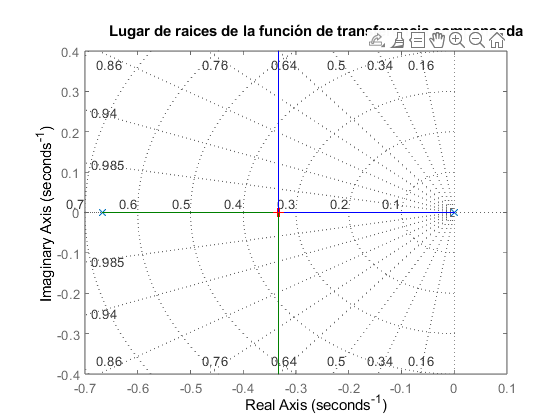

grid on;

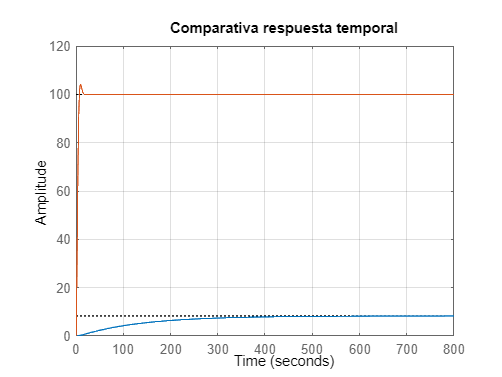


% El valor que satisface los requerimientos es kp = 1
figure;
kp=272;
step(feedback(G,H),feedback(kp*G*PID,H));
grid on;
title('Comparativa respuesta temporal');

legend('no compensado', 'compensado')

%Nota:El lugar de racies tiene como resultado una fdt que es inestable para
%todo kp, la unica forma de hacerlo estable es utilizar un kp negativo (es decir,
% un incremento en la entrada reduce la salida)  

% Diseño del PI
% La forma del PI es: PI = kp(s+1/Ti)/s

% Teniendo en cuenta que el polo dominante es s=-0.007 tenemos:
Ti=1/0.007

% Armamos el controlador PI utilizando los valores de Ti
PI = (s+1/Ti)/s

% Armamos la funcion de transferencia a lazo abierto compensado (con PI)
FdT_Global_PI = PI*GH

% Verificamos la cancelacion de polos
figure;
subplot(2,1,1);                  % Primer subplot para la funcion a lazo abierto
pzmap(GH);       % Muestra el mapa de polos y ceros de la funcion a lazo abierto
title('Mapa de Polos y Ceros a lazo abierto "GH"');
xlabel('real');
ylabel('imaginaria');
grid on;

subplot(2,1,2);          % Segundo subplot para la funcion con PI
pzmap(FdT_Global_PI);  % Muestra el mapa de polos y ceros de la funcion compensada
title('Mapa de Polos y Ceros con Controlador PI');
xlabel('real');
ylabel('imaginaria');
grid on;

% Simplificamos la expresion para obtener una forma mas compacta
FdT_Global_PI = minreal(FdT_Global_PI)  % Simplificacion de la fdt

figure;
rlocus(FdT_Global_PI);         
grid on;                          
title('Lugar de raices de la función de transferencia compensada');

%Nota:Idem al anterior inestable para todo kp, podria usar un kp negativo

% Diseño del PD
% La forma del PI es: PID = kpTd(s+1/Td)

% Teniendo en cuenta que el polo dominante es s=-0.007 tenemos:
Td=1/0.007

% Armamos el controlador PI utilizando los valores de Ti
PD = Td*(s+1/Td)

% Armamos la funcion de transferencia a lazo abierto compensado (con PD)
FdT_Global_PD = PD*GH


% Verificamos la cancelacion de polos
figure;
subplot(2,1,1);                  % Primer subplot para la funcion a lazo abierto
pzmap(GH);       % Muestra el mapa de polos y ceros de la funcion a lazo abierto
title('Mapa de Polos y Ceros a lazo abierto "GH"');
xlabel('real');
ylabel('imaginaria');
grid on;

subplot(2,1,2);          % Segundo subplot para la funcion con PI
pzmap(FdT_Global_PD);  % Muestra el mapa de polos y ceros de la funcion compensada
title('Mapa de Polos y Ceros con Controlador PD');
xlabel('real');
ylabel('imaginaria');
grid on;

% Simplificamos la expresion para obtener una forma mas compacta
FdT_Global_PD = minreal(FdT_Global_PD)  % Simplificacion de la fdt

figure;
rlocus(FdT_Global_PD);         
grid on;                         
title('Lugar de raices de la función de transferencia compensada');

%Estable para kp<11
rlocfind(FdT_Global_PD);
grid on;

% El valor que satisface los requerimientos es kp = 1
figure;
kp=1;
step(feedback(G,H),feedback(kp*G*PD,H));
grid on;
title('Comparativa respuesta temporal');
legend('no compensado', 'compensado')


%Analisis del error en estado estable, la fdt global resulta un sistema de
%tipo 0, por lo tanto se espera que el error en estado estable sea
%constante.

R=1; %amplitud escalon
kp=evalfr(G*H*PD,0);

disp('Error de estado estable resulta: ');
ess=R/(1+kp)